close all
clear all
load("CPDAS.mat");
trace_1 = trace(1,:);
trace_2 = trace(15,:);
trace_1 = f_traze_complex2int16(trace_1,"trace_1");

trace_1:

max_from_trace = 2.2937

scale_factor = 1.4285e+04

trace_2 = f_traze_complex2int16(trace_2,"trace_2");

trace_2:

max_from_trace = 2.2936

scale_factor = 1.4286e+04

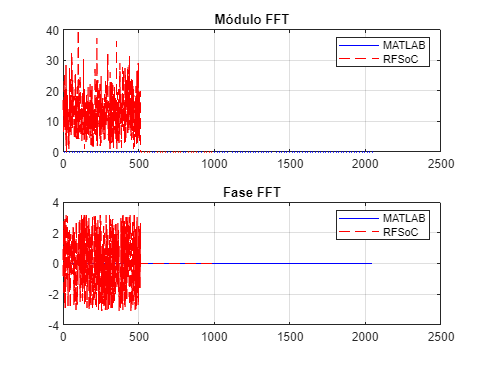

%% Leer FFT de la RFSoC
fid = fopen('fft_in_rfsoc.bin','rb');
tmp = fread(fid,'int16');
fclose(fid);

fft_rfsoc = complex(tmp(1:2:end), tmp(2:2:end));

%% Primera ventana de la traza
N = 2048;
trace_win = trace_2(N*5:N*6);

%% FFT de MATLAB
fft_matlab = fft(trace_win);

%% Comparación
figure;

subplot(2,1,1)
plot(abs(fft_matlab),'b'); hold on;
plot(abs(fft_rfsoc),'r--');
grid on;
legend('MATLAB','RFSoC');
title('Módulo FFT');

subplot(2,1,2)
plot(angle(fft_matlab),'b'); hold on;
plot(angle(double(fft_rfsoc)),'r--');
grid on;
legend('MATLAB','RFSoC');
title('Fase FFT');

#### FFT y conjugada de traza 1

window   = 1024;
nfft  = 2048;
rbins = nfft/2 + 1;
% trace_1 int16 
trace_1 = trace_1(:);
num_win = floor(length(trace_1)/window);
trace_1 = trace_1(1:num_win*window);
% ventaneo
trace1_sliced = reshape(double(trace_1), window, num_win);
% padding
trace1_padded = [trace1_sliced; zeros(window, num_win)];
% FFT 
X1 = fft(trace1_padded, nfft, 1);
ref_conj = conj(X1(1:rbins, :));
% export
f_traze_conj_header(ref_conj, "ref_conj");

#### FFT R2C con entrada int16 Matlab

% FFT de traza en int16 por ventanas sin solape con paddinga 2*window (equivalente a FPGA)
window = 1024;
nfft   = 2048;
rbins  = nfft/2 + 1;
trace_2 = trace_2(:); % vector columna
scale_factor = 1.8054e+04;
% ventaneo
num_win = floor(length(trace_2)/window); % si no es 127 está mal
trace_2 = trace_2(1:num_win*window);
trace_2_sliced = reshape(double(trace_2), window, num_win);   % cada columna = una ventana

% padding (añadir 1024 ceros debajo) -> [nfft x num_win]
trace_2_padded = [trace_2_sliced; zeros(window, num_win)];

% FFT por columnas y quedarnos con bins 0..N/2
trace_2_fft = fft(trace_2_padded, nfft, 1);
mat_fft = trace_2_fft(1:rbins, :)/scale_factor;

#### FFT R2C con entrada int16  (FPGA)

fid = fopen('fft_out_rfsoc2.bin','rb');
ne10_raw = fread(fid,'int16');
fclose(fid);

% assert(mod(numel(ne10_raw),2)==0); % Comprueba que el numero de bins es par (real + img = 2 bins)

Re = ne10_raw(1:2:end);
Im = ne10_raw(2:2:end);
ne10_complex = double(Re) + 1j*double(Im);

num_win = length(ne10_complex)/rbins;
ne10_fft = reshape(ne10_complex, rbins, num_win)/scale_factor; % No entiendo por que el  / (2^15)

A = (mat_fft);
B = (ne10_fft);      

% --- Ajuste de escala
alpha = (A(:)'*B(:)) / (A(:)'*A(:));
A = alpha*A;

err_rms = rms(B - A, 1);


% Error promedio por ventana
err = B - A;
err_mean = mean(abs(err), 1);
figure;
plot(1:num_win, err_mean, '-o'); grid on;
xlabel('Ventana');
ylabel('Error medio por ventana)');
title(sprintf('Error medio por ventana (%d ventanas)', num_win));

% Error max por ventana
err = B - A;
err_max = max(abs(err));
figure;
plot(1:num_win, err_max, '-o'); grid on;
xlabel('Ventana');
ylabel('Error máximo por ventana)');
title(sprintf('Error máximo por ventana (%d ventanas)', num_win));

% Error relativo RMS por ventana
err_rms = rms(B - A, 1);
figure;
plot(1:num_win, err_rms, '-o');
grid on;
xlabel('Ventana');
ylabel('Error rms');
title(sprintf('Error por ventana (rms)  (%d ventanas)', num_win));
% --- Plot de una ventana concreta ---
k = 40;
figure;
plot(abs(A(:,k)),'.'); hold on;
plot(abs(B(:,k)),'-');
grid on;
xlabel('Bin (0..N/2)');
ylabel('|FFT|');
title(sprintf('Ventana %d: |FFT| (\\alpha·MATLAB vs Vitis)', k));
legend('\alpha·MATLAB','Vitis');

#### Correlación directa entre trazas raw

window = 1024;
x = trace_1(:) ;
y = trace_2(:);
x = x - mean(x);
y = y - mean(y);
num_win = floor(min(length(x),length(y)) / window);
retardos = nan(1,num_win);
for i = 1:num_win
    idx = 1+(i-1)*window : i*window;

    r = xcorr(y(idx), x(idx));           % tamaño 2*window-1
    lags = -(window-1):(window-1);

    [~,imax] = max(abs(r));
    retardos(i) = lags(imax);
end

figure; plot(retardos,'-o'); grid on;
xlabel('Ventana'); ylabel('Muestras de retardo');
title('Retardo máximo por ventana usando xcorr');

#### Correlación entre FFT de traza X (Ne10) y Conjugada de FFT de traza 1 (Matlab)

% ne10_fft: FFT traza2 desde FPGA, compleja
% ref_conj: conj FFT traza1 en MATLAB, misma segmentación

num_window = 127;
frec_prod = ne10_fft(:,1:num_window) .* ref_conj(:,1:num_window);   % producto en frecuencia (bins únicos)

% Para IFFT a 2048 muestras necesitas espectro completo:
% reconstrucción Hermítica (real time-domain)
nfft    = 2048;
window  = 1024;
rbins   = nfft/2+1;

Yfull = zeros(nfft, num_window);
Yfull(1:rbins,:) = frec_prod;

% completar bins negativos: num_window=RBINS+1..NFFT con conjugado
% Y[N-num_window] = conj(Y[num_window])  -> en MATLAB índices:
% Yfull(RBINS+1:end,:) = conj( flipud( Yf(2:end-1,:) ) );
Yfull(rbins+1:end,:) = conj(flipud(frec_prod(2:end-1,:)));

corr_t = ifft(Yfull, nfft, 1);
corr_t = fftshift(corr_t, 1);         % lags centrados
corr_abs = abs(corr_t);

lags = -window:window-1;
[~,idx] = max(corr_abs,[],1);
retardos = lags(idx);

figure; plot(retardos,'-o'); grid on;
xlabel('Ventana'); ylabel('Lag (muestras)');
title('Lag máximo por ventana (FPGA FFT * conj(ref))');

#### Correlación entre FFT de traza X (Ne10) y Conjugada de FFT de traza 1 (Matlab) 

Correlación calculada también en FPGA (micro)

% ===== Cargar corr_out.bin (int32) y graficar por ventanas =====
close all; clear; clc;

NFFT   = 2048;
WIN    = 1024;                 % para lags [-WIN..WIN-1]
file   = 'corr_out.bin';

% 1) leer binario
fid = fopen(file,'rb');
corr_raw = fread(fid,'int32');
fclose(fid);

% 2) reshape a [NFFT x num_win]
num_win = floor(numel(corr_raw)/NFFT);
corr_raw = corr_raw(1:num_win*NFFT);
corr_t = reshape(corr_raw, NFFT, num_win);   % cada columna = una ventana

% 3) centrar lags (opcional pero recomendable)
corr_t = fftshift(corr_t, 1);

% 4) lag máximo por ventana
corr_abs = abs(corr_t);
lags = -WIN:WIN-1;

[~, idx] = max(corr_abs, [], 1);
retardos = lags(idx);

% 5) plots

figure;
plot(1:num_win, retardos, '-o'); grid on;
xlabel('Ventana'); ylabel('Desplazamientos para pico de correlada');
title('Desplazamiento del máximo por ventana');

% (opcional) ver una ventana concreta
k = 113;
figure;
plot(lags, corr_abs(:,k)); grid on;
xlabel('Desplazamiento'); ylabel('correlada');
title(sprintf('corr ventana %d', k));

#### Plot de las convoluciones de FPGA y MATLAB

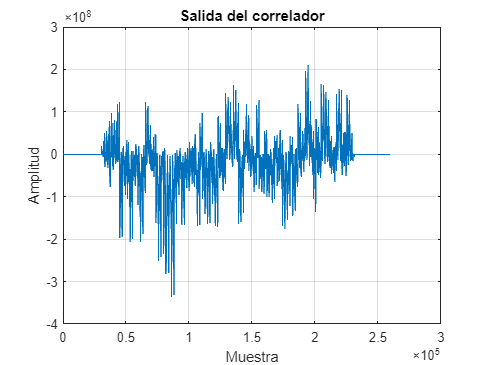

clear
close all
clc

fid = fopen('corr_out_rfsoc.bin','rb');
corr = fread(fid, Inf, 'int32');
fclose(fid);

figure;
plot(corr);
grid on;
xlabel('Muestra');
ylabel('Amplitud');
title('Salida del correlador');

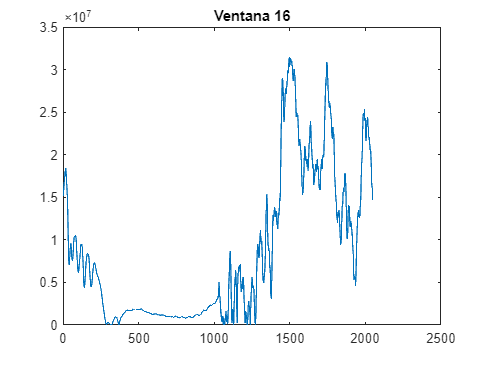


NFFT = 2048;
corr = reshape(corr,NFFT,[]);
figure
plot(abs(corr(:,16)))
title('Ventana 16')

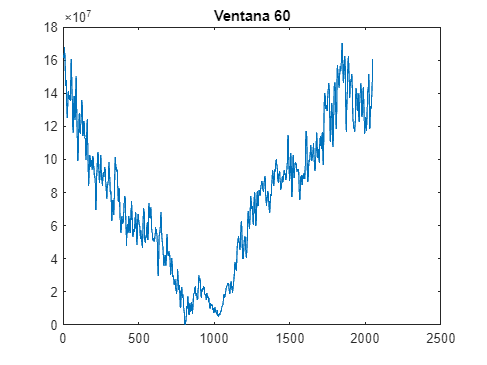

figure
plot(abs(corr(:,60)))
title('Ventana 60')

#### Error de la convolución (FPGA vs Matlab)

% Error promedio por ventana
err = B - A;
err_mean = mean(abs(err), 1);
figure;
plot(1:num_win, err_mean, '-o'); grid on;
xlabel('Ventana');
ylabel('Error medio por ventana)');
title(sprintf('Error medio por ventana (%d ventanas)', num_win));

% Error max por ventana
err = B - A;
err_max = max(abs(err));
figure;
plot(1:num_win, err_max, '-o'); grid on;
xlabel('Ventana');
ylabel('Error máximo por ventana)');
title(sprintf('Error máximo por ventana (%d ventanas)', num_win));

% Error relativo RMS por ventana
err_rms = rms(B - A, 1);
figure;
plot(1:num_win, err_rms, '-o');
grid on;
xlabel('Ventana');
ylabel('Error rms');
title(sprintf('Error por ventana (rms)  (%d ventanas)', num_win));

